clear all;
close all;

## Parameter Angabe

Hier werden die Parameter wie Konstanten für die komplette Berechnung vorgegeben.

format shortG
doy = 291;      % day
time = 12;      % sec
phi = 47.26;    % ° Innsbruck
P_0 = 200;      % W/m²
selected_days = {'2024-03-21', '2024-06-21', '2024-10-21', '2024-12-21'};

dates = datetime(2024, 1, 1):datetime(2024, 12, 31);
formatted_dates = datestr(dates, 'yyyy-mm-dd'); % Umrechung auf ein Datenformat

%Berechnung der Deklination, des Stunden- Höhenwinkel und Azimutwinkels
%delta = Deklination(doy)
%H = Stundenwinkel(time)
%alpha_h = Hohenwinkel(time, doy, phi)
%alpha_a = Azimut(time, doy, phi)

## Taglänge

Hier wird mit der Funktion "Tageslange" die Tageslänge über ein komplettes Jahr berechnet. Anschließend wird dies geplottet um ein besseres Verständis zu übermitteln.

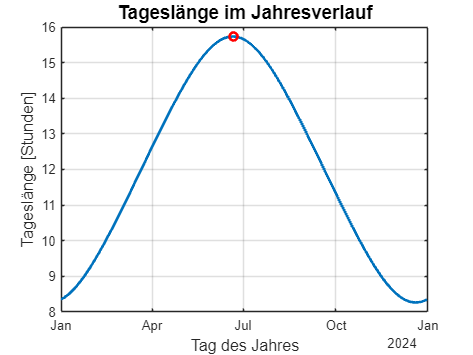

day_length = Tageslange(dates, phi);
[max_day_lenght, max_date] = max(day_length);
plot(dates, day_length, 'LineWidth', 2);
hold on
scatter(max_date, max_day_lenght, 'ro', 'LineWidth', 2);
hold off
grid on;

title('Tageslänge im Jahresverlauf', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Tag des Jahres', 'FontSize', 12);
ylabel('Tageslänge [Stunden]', 'FontSize', 12);


max_date = datetime(2024, 1, 1) + days(max_date - 1);
fprintf('Längster Tag: %s\n', datestr(max_date));

Längster Tag: 20-Jun-2024


disp('=============================================');

## Vektor zur Sonne

Hier wird der Höhenwinkel über ein ganzes Jahr hinweg berechnet. Die Berechnung erfolgt mittels Sonnenvektor in dem der arcsin von der Z-Achse genommen wird.

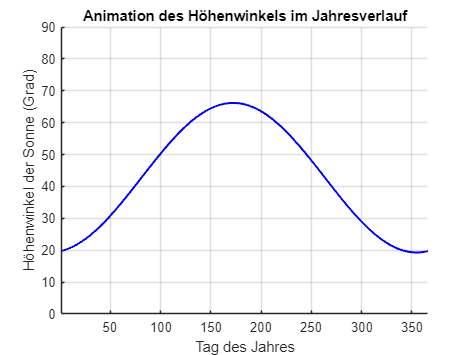

figure;
hold on;
grid on;
xlabel('Tag des Jahres');
ylabel('Höhenwinkel der Sonne (Grad)');
title('Animation des Höhenwinkels im Jahresverlauf');
ylim([0, 90]); 
xlim([1, length(dates)]);
plot_handle = plot(0, 0, 'b-', 'LineWidth', 1.5);

heights = zeros(1, length(dates));

for i = 1:length(dates)
    
    form_date = formatted_dates(i, :);
    s = Sonneneinheitsvektor(form_date, phi);
    
    max_height = asind(max(s(3, :))); 
    heights(i) = max_height; 
    
    set(plot_handle, 'XData', 1:i, 'YData', heights(1:i));
    drawnow;
    pause(0.05);
end

hold off;

## Tagessumme horizontale Anlage

Hier wird die Tagesenergie für eine horiozontal ausgerichtete PV-Anlage über ein Jahr hinweg sowie die Tagesenergie für bestimmte Tage berechnet.

Zur Berechnung der Energie wird die selbstgeschriebene Funktion "Tagesenergie" verwendet, dabei wird nur die Energie in der Zeitspanne zwischen Sonnnenauf und -untergang berücksichtigt. 

Der Vektor n beschreibt den Einheitsvektor der PV-Anlage.

Anschließend werden die Ergebnisse über das Jahr geplottet.

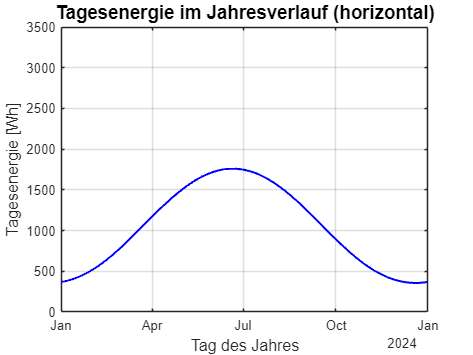

n = [0; 0; 1];

yearly_energy_h = 0;
daily_energies_h = ones(length(formatted_dates), 1);
for i = 1:length(formatted_dates)
    day = formatted_dates(i, :);
    daily_energy_h = Tagesenergie(day, phi, n, P_0);
    yearly_energy_h = yearly_energy_h + daily_energy_h;
    daily_energies_h(i) = daily_energy_h;
end

figure;
plot(dates, daily_energies_h, 'b-', 'LineWidth', 1.5); % Rohdaten
title('Tagesenergie im Jahresverlauf (horizontal)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Tag des Jahres', 'FontSize', 12);
ylabel(['Tagesenergie [Wh]'], 'FontSize', 12);
grid on;
ylim([0 3500]);


results = table(selected_days', zeros(length(selected_days), 1), ...
    'VariableNames', {'Datum', 'Tagesenergie_Wh'});
for k = 1:length(selected_days)
    day = selected_days{k};
    horizontal_P = Tagesenergie(day, phi, n, P_0);
    results.Tagesenergie_Wh(k) = horizontal_P;
end

disp(results);

        Datum         Tagesenergie_Wh
    ______________    _______________

    {'2024-03-21'}        1036.9     
    {'2024-06-21'}        1759.5     
    {'2024-10-21'}        671.73     
    {'2024-12-21'}        356.85     



fprintf('Gesamtenergie über Jahr %d = %.2f Wh\n', 2024, yearly_energy_h);

Gesamtenergie über Jahr 2024 = 382407.46 Wh


disp('=============================================');

## Tagessumme Vertikale Anlage

Diese Berechnung ähnelt der Berechnung der Tagesenergie der horizontal ausgerichteten PV-Anlage jedoch wurde hier der n Vektor abgeändert, um eine vertikal ausgerichtete PV-Anlage zu beschreiben. Es ist wichtig zu beachten, dass man -1 in die y-Richung geht, da man die PV-Anlage Richtung Süden ausrichten will.

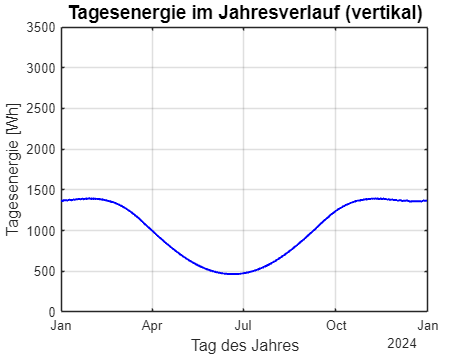

n = [0; -1; 0];

yearly_energy_v = 0;
daily_energies_v = ones(length(formatted_dates), 1);
for i = 1:length(formatted_dates)
    day = formatted_dates(i, :);
    daily_energy_v = Tagesenergie(day, phi, n, P_0);
    yearly_energy_v = yearly_energy_v + daily_energy_v;
    daily_energies_v(i) = daily_energy_v;
end

figure;
plot(dates, daily_energies_v, 'b-', 'LineWidth', 1.5);
title('Tagesenergie im Jahresverlauf (vertikal)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Tag des Jahres', 'FontSize', 12);
ylabel('Tagesenergie [Wh]', 'FontSize', 12);
grid on;
ylim([0 3500]);


results_vertical = table(selected_days', zeros(length(selected_days), 1), ...
    'VariableNames', {'Datum', 'Tagesenergie_Wh'});

for k = 1:length(selected_days)
    day = selected_days{k};
    vertical_P = Tagesenergie(day, phi, n, P_0);
    results_vertical.Tagesenergie_Wh(k) = vertical_P;
end

disp(results_vertical);

        Datum         Tagesenergie_Wh
    ______________    _______________

    {'2024-03-21'}        1122.1     
    {'2024-06-21'}         465.2     
    {'2024-10-21'}        1363.3     
    {'2024-12-21'}        1359.3     



fprintf('Gesamtenergie über Jahr %d = %.2f Wh\n', 2024, yearly_energy_v);

Gesamtenergie über Jahr 2024 = 373398.80 Wh


disp('=============================================');

## Optimale Auslegung

Hier wird ebenfalls die Tagesenergie über ein Jahr berechnet, jedoch für eine PV-Anlage mit optimal ausgelegten Winkeln. 

Hierfür wird zuerst der optimale Winkel für jeden Tag mittels fminsearch ermittelt und anschließend der Mittelwert gezogen. 

An der Berechnung der Tagesenergie ändert sich nichts. 

Um den Energieertrag zu veranschaulichen wird am Ende der Berechnung ein Faktor berechnet der den Zusammenhang zwischen vertikaler und optimaler PV-Anlage und horizontaler und optimaler PV-Anlage darstellt.

startwerte = [10, 0]; %Startwerte für fminsearch

beta_opt = zeros(length(dates), 1);
gamma_opt = zeros(length(dates), 1);

for i = 1:length(dates)
    fday = formatted_dates(i, :);
    
    options = optimset('MaxFunEvals', 365, 'Display', 'off');
    optimal_winkel = fminsearch(@(x) -(berechne_Tagesenergie_Winkel(x, phi, fday, P_0)), startwerte, options);

    beta_opt(i) = optimal_winkel(1);    % Optimale Neigung
    gamma_opt(i) = -optimal_winkel(2);  % Optimale Ausrichtung
end

beta_opt = mean(beta_opt);
gamma_opt = mean(gamma_opt);

fprintf('Optimale Neigung: %.2f°\n', beta_opt);

Optimale Neigung: 62.39°


fprintf('Optimale Ausrichtung: %.2f°\n', gamma_opt);

Optimale Ausrichtung: 33.73°


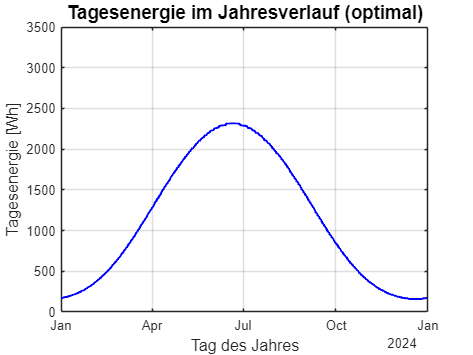


yearly_energy_o = 0;
daily_energies_o = ones(length(formatted_dates), 1);
for i = 1:length(formatted_dates)
    day = formatted_dates(i, :);
    daily_energy_o = berechne_Tagesenergie_Winkel([beta_opt gamma_opt], phi, day, P_0);
    yearly_energy_o = yearly_energy_o + daily_energy_o;
    daily_energies_o(i) = daily_energy_o;
end

figure;
plot(dates, daily_energies_o, 'b-', 'LineWidth', 1.5);
title('Tagesenergie im Jahresverlauf (optimal)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Tag des Jahres', 'FontSize', 12);
ylabel('Tagesenergie [Wh]', 'FontSize', 12);
grid on;
ylim([0 3500]);


results_optimal = table(selected_days', zeros(length(selected_days), 1), ...
    'VariableNames', {'Datum', 'Tagesenergie_Wh'});

for k = 1:length(selected_days)
    day = selected_days{k};
    Perfekt_P = berechne_Tagesenergie_Winkel([beta_opt gamma_opt], phi, day, P_0);
    results_optimal.Tagesenergie_Wh(k) = Perfekt_P;
end

disp(results_optimal);

        Datum         Tagesenergie_Wh
    ______________    _______________

    {'2024-03-21'}        1071.4     
    {'2024-06-21'}        2316.1     
    {'2024-10-21'}        535.53     
    {'2024-12-21'}        158.94     



fprintf('Gesamtenergie über Jahr %d = %.2f Wh\n', 2024, yearly_energy_o);

Gesamtenergie über Jahr 2024 = 419686.12 Wh



faktor_oh = yearly_energy_o / yearly_energy_h;
faktor_ov = yearly_energy_o / yearly_energy_v;
fprintf('Faktor: optimierter / horizontaler = %.2f\n', faktor_oh);

Faktor: optimierter / horizontaler = 1.10


fprintf('Faktor: optimierter / vertikaler = %.2f\n', faktor_ov);

Faktor: optimierter / vertikaler = 1.12



disp('=============================================');

## Nachgeführte Anlage (ein oder zwei Achsen)

Bei der nachgeführten Anlage ist der n-Vektor der PV-Anlage gleich des s-Vektors der Sonne, somit hat man zu jedem Zeitpunkt den maximalen Energieertrag. Ansonsten ändert sich die Berechnung kaum.

Wichtig zu erwähnen ist dass nur die zweiachsig nachgeführte Anlage betrachtet wurde.

Die Faktoren zwischen den verschiedenen Ausrichtungsarten wird hier ebenfalls berechnet.

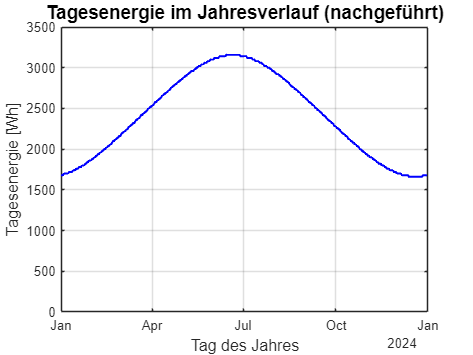

yearly_energy_nachgefuhrt = 0;
daily_energies_n = ones(length(formatted_dates), 1);
for i = 1:length(formatted_dates)
    day = formatted_dates(i, :);
    daily_energy_n = Tagesenergie_nachgefuhrt(day, phi, P_0);
    yearly_energy_nachgefuhrt = yearly_energy_nachgefuhrt + daily_energy_n;
    daily_energies_n(i) = daily_energy_n;
end

days = 1:length(formatted_dates);
figure;
plot(dates, daily_energies_n, 'b-', 'LineWidth', 1.5);
title('Tagesenergie im Jahresverlauf (nachgeführt)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Tag des Jahres', 'FontSize', 12);
ylabel('Tagesenergie [Wh]', 'FontSize', 12);
grid on;
ylim([0 3500]);


fprintf('Gesamtenergie über Jahr %d = %.2f Wh\n', 2025, yearly_energy_nachgefuhrt);

Gesamtenergie über Jahr 2025 = 881340.00 Wh



Faktor_nh = yearly_energy_nachgefuhrt / yearly_energy_h;
fprintf('Faktor: nachgeführter / horizontaler = %.2f\n', Faktor_nh);

Faktor: nachgeführter / horizontaler = 2.30


Faktor_nv = yearly_energy_nachgefuhrt / yearly_energy_v;
fprintf('Faktor: nachgeführter / vertikaler = %.2f\n', Faktor_nv);

Faktor: nachgeführter / vertikaler = 2.36


Faktor_no = yearly_energy_nachgefuhrt / yearly_energy_o;
fprintf('Faktor: nachgeführte / optimaler = %.2f\n', Faktor_no);

Faktor: nachgeführte / optimaler = 2.10



disp('=============================================');

## Vergleich

Alle zuvor berechneten PV-Ausrichtungen werden hier auf einen Plot gezeichnet um einen besseren Vergleich zu ermöglichen.

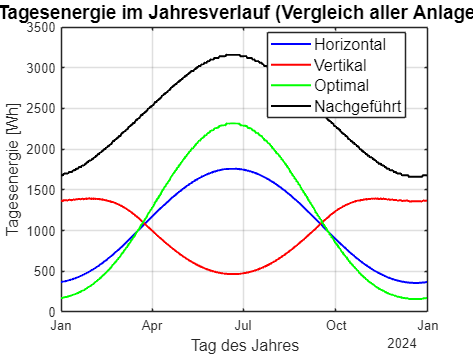

figure;

% Plot horizontale Anlage
plot(dates, daily_energies_h, 'b-', 'LineWidth', 1.5); hold on;

% Plot vertikale Anlage
plot(dates, daily_energies_v, 'r-', 'LineWidth', 1.5);

% Plot optimale Anlage
plot(dates, daily_energies_o, 'g-', 'LineWidth', 1.5);

% Plot nachgeführte Anlage
plot(dates, daily_energies_n, 'k-', 'LineWidth', 1.5);

title('Tagesenergie im Jahresverlauf (Vergleich aller Anlagen)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Tag des Jahres', 'FontSize', 12);
ylabel('Tagesenergie [Wh]', 'FontSize', 12);

legend({'Horizontal', 'Vertikal', 'Optimal', 'Nachgeführt'}, 'Location', 'best', 'FontSize', 12);

grid on;
ylim([0 3500]);

hold off;

disp('=============================================')

## Funktionen

function delta = Deklination(doy)
    % Berechnung der solaren Deklination (Winkel zwischen Sonne und Äquator)
    % doy: Tag des Jahres

    delta = 23.45 * sind((360 / 365) * (doy + 284));
end

function alpha_H = Stundenwinkel(t)
    % Berechnung des Stundenwinkels der Sonne (Winkel, basierend auf Tageszeit)
    % t: Uhrzeit (in Stunden)

    alpha_H = 15 * (t - 12); % t in Stunden
end

function alpha_h = Hohenwinkel(t, doy, phi)
    % Berechnung des Höhenwinkels der Sonne (Winkel zwischen Sonne und Horizont)
    % t: Uhrzeit (in Stunden)
    % doy: Tag des Jahres
    % phi: geografische Breite (in Grad)

    alpha_h = asind((sind(phi) * sind(Deklination(doy))) + ...
                   (cosd(phi) * cosd(Deklination(doy)) * cosd(15 * (t - 12))));
end

function alpha_z = Azimut(t, doy, phi)
    % Berechnung des Azimutwinkels der Sonne (horizontaler Winkel zur Nordrichtung)
    % t: Uhrzeit (in Stunden)
    % doy: Tag des Jahres
    % phi: geografische Breite (in Grad)

    delta = Deklination(doy);
    alpha_h = Hohenwinkel(t, doy, phi);

    alpha_z = acosd((sind(delta) - sind(alpha_h) * sind(phi)) / ...
                    (cosd(alpha_h) * cosd(phi)));
end

function [day_length, time_up, time_down] = Tageslange(whatDay, phi)
    % Berechnung der Tageslänge, Sonnenaufgang und Sonnenuntergang
    % whatDay: Datum im Format 'YYYY-MM-DD'
    % phi: geografische Breite (in Grad)

    doy = day(datetime(whatDay), "dayofyear");
    delta = Deklination(doy);

    time_up = -(acosd(-tand(phi) * tand(delta)) / 15) + 12;
    time_down = (acosd(-tand(phi) * tand(delta)) / 15) + 12;
    day_length = time_down - time_up;
end

function s = Sonneneinheitsvektor(whatDay, phi)
    % Berechnung des Sonnenpositionsvektors (normalisiert) für jeden Zeitpunkt des Tages
    % whatDay: Datum im Format 'YYYY-MM-DD'
    % phi: geografische Breite (in Grad)

    doy = day(datetime(whatDay), "dayofyear");
    [~, time_up, time_down] = Tageslange(whatDay, phi);

    time_range = time_up:0.1:time_down;
    s = zeros(3, length(time_range));

    for i = 1:length(time_range)
        alpha_h = Hohenwinkel(time_range(i), doy, phi);
        alpha_z = Azimut(time_range(i), doy, phi);

        % Umrechnung in kartesische Koordinaten
        x = cosd(alpha_h) * sind(alpha_z);
        y = cosd(alpha_h) * cosd(alpha_z);
        z = sind(alpha_h);

        s(:, i) = [x; y; z];
    end
end

function max_P = Tagesenergie(day, phi, n, P_0)
    % Berechnung der Tagesenergie für eine gegebene PV-Ausrichtung
    % day: Datum im Format 'YYYY-MM-DD'
    % phi: geografische Breite (in Grad)
    % n: Einheitsvektor der PV-Fläche
    % P_0: Einstrahlungsleistung (in W/m²)

    s = Sonneneinheitsvektor(day, phi);
    power = zeros(1, size(s, 2));

    for i = 1:size(s, 2)
        cos_theta = dot(s(:, i), n) / (norm(s(:, i)) * norm(n));
        power(i) = P_0 * max(cos_theta, 0) * 0.1;
    end

    max_P = sum(power);
end

function max_P = berechne_Tagesenergie_Winkel(beta_gamma, phi, day, P_0)
    % Berechnung der Tagesenergie für eine optimale Ausrichtung
    % beta_gamma: [Neigungswinkel (beta), Azimutwinkel (gamma)]
    % day: Datum im Format 'YYYY-MM-DD'
    % phi: geografische Breite (in Grad)
    % P_0: Einstrahlungsleistung (in W/m²)

    beta = beta_gamma(1);
    gamma = beta_gamma(2);
    pv_normal = [sind(beta) * cosd(gamma), sind(beta) * sind(gamma), cosd(beta)];
    s = Sonneneinheitsvektor(day, phi);
    power = zeros(1, size(s, 2));

    for i = 1:size(s, 2)
        norm_s = norm(s(:, i));
        norm_pv = norm(pv_normal);
        if norm_s == 0 || norm_pv == 0
            cos_theta = 0;
        else
            cos_theta = dot(s(:, i), pv_normal) / (norm_s * norm_pv);
        end
        power(i) = P_0 * max(cos_theta, 0) * 0.1;
    end

    max_P = sum(power);
end

function max_P = Tagesenergie_nachgefuhrt(day, phi, P_0)
    % Berechnung der Tagesenergie für eine nachgeführte PV-Anlage
    % day: Datum im Format 'YYYY-MM-DD'
    % phi: geografische Breite (in Grad)
    % P_0: Einstrahlungsleistung (in W/m²)

    s = Sonneneinheitsvektor(day, phi);
    power = zeros(1, size(s, 2));

    for i = 1:size(s, 2)
        cos_theta = dot(s(:, i), s(:, i)) / (norm(s(:, i)) * norm(s(:, i)));
        power(i) = P_0 * max(cos_theta, 0) * 0.1;
    end

    max_P = sum(power);
end